# Hands-On: the Covariance Matrix

## Introduction

In this section, we offer a basic introduction to the covariance matrix and its use in system identification for the readers who are less familiar with statistics.

What you will learn:

- Introduction of the covariance matrix

- Understanding the role of the variance and covariance

- Introduction of the correlation matrix

- Studying the variance of a multivariate function

- Difference between correlated and independent variables.

## Motivation

Statistical tools are intensively used in system identification. The disturbances in the experimental data are modeled as random variables, and hence also the models obtained from these data have a random behavior. 

A real random variable $X\in \mathbb{R}^{n\times1}$ is fully characterized by its probability distribution function $F_X(x)=P(X\leq x)$ or, under weak conditions, by its probability density function (pdf) $f_X(x)$. 

In many problems, the normal (or Gaussian) distribution is used. A normal distribution is characterized by its mean value $\mu = E[X]$ and covariance matrix $C\in \mathbb{R}^{n\times n}$:

$C=E[(X-\mu)(X-\mu)^t]$. 

The covariance matrix describes how the estimate is scattered around its mean value.

- The diagonal entries $C_{ii}$ of the covariance matrix are the variances $\sigma_i^2=E[(X_i-\mu_i)^2]$.  

- The off-line elements $C_{ij}$  are the covariances  $\sigma_{ij}^2=E[(X_i-\mu_i)(X_j-\mu_j)]$.  

-  The correlation coefficient $\rho_{ij}=\frac{\sigma_{ij}^2}{\sigma_i \sigma_j}$ , with $-1 \leq \rho_{ij} \leq 1$, describes the strength of the linear relation between $X_i$ and $X_j$.  A value of 1 and -1 indicate a perfect linear relation with respectively a positive or negative slope. $\rho_{ij}=0$ indicates that there is no linear relation between $X_i$ and $X_j$.

## The Covariance and Correlation Matrix

In this demo we generate $N$ samples of a two-dimensional normal distribution $X\sim N(0,C)$with zero mean and covariance matric $C$.  The reader can set the number $N$, the variances $c11= \sigma_1^2, c22= \sigma_2^2$, and the correlation coefficient $rho=\rho_{12}=\frac{\sigma_{12}^2}{\sigma_1 \sigma_2}.$  A scatter plot of $X$, together with the estimated pdf of $X_1$ and $X_2$ are shown. The covariance and correlation matrix are estimated and displayed below the figure. Study the following settings:

- Put c11=5, c22=1, rho=0. The following observations can be made. $X_1,X_2$ are normally distributed with zero mean. The width of the distribution is set by the standard deviations $\sigma_1, \sigma_2$ (the square root of the variances). The scatter plot is elliptically shaped. In red, the ellipse with a probability of 95% is drawn. The lengths of the main axes of the ellipse are set by the standard deviations. The orientation of the ellipse is controlled by the value of rho.

- Put rho=0.5. Observe that the distributions of $X_1,X_2$ do not change, but the ellipse rotates. This reflects that there is a (weak) linear relation between $X_1$ and $X_2$. For positive values of rho, the slope will be positive.

- Increasing the value of rho to rho=1 results in a perfect linear relation between $X_1$ and $X_2$.

- For negative values of rho, the slope becomes negative. Again a perfect linear relation is retrieved for rho=-1.

- Observe that the values of the estimated covariance and correlation matrix are not equal to the true values that you set. Their values varies also when the simulation is repeated. Change the number of samples $N$, select a small and large value. For smaller values of $N$, the variation of the estimates becomes larger than for larger values. This is a typical observation for estimated values. When the number of data points grows, the uncertainty on the estimates drops. This will be further studied in the identification section.

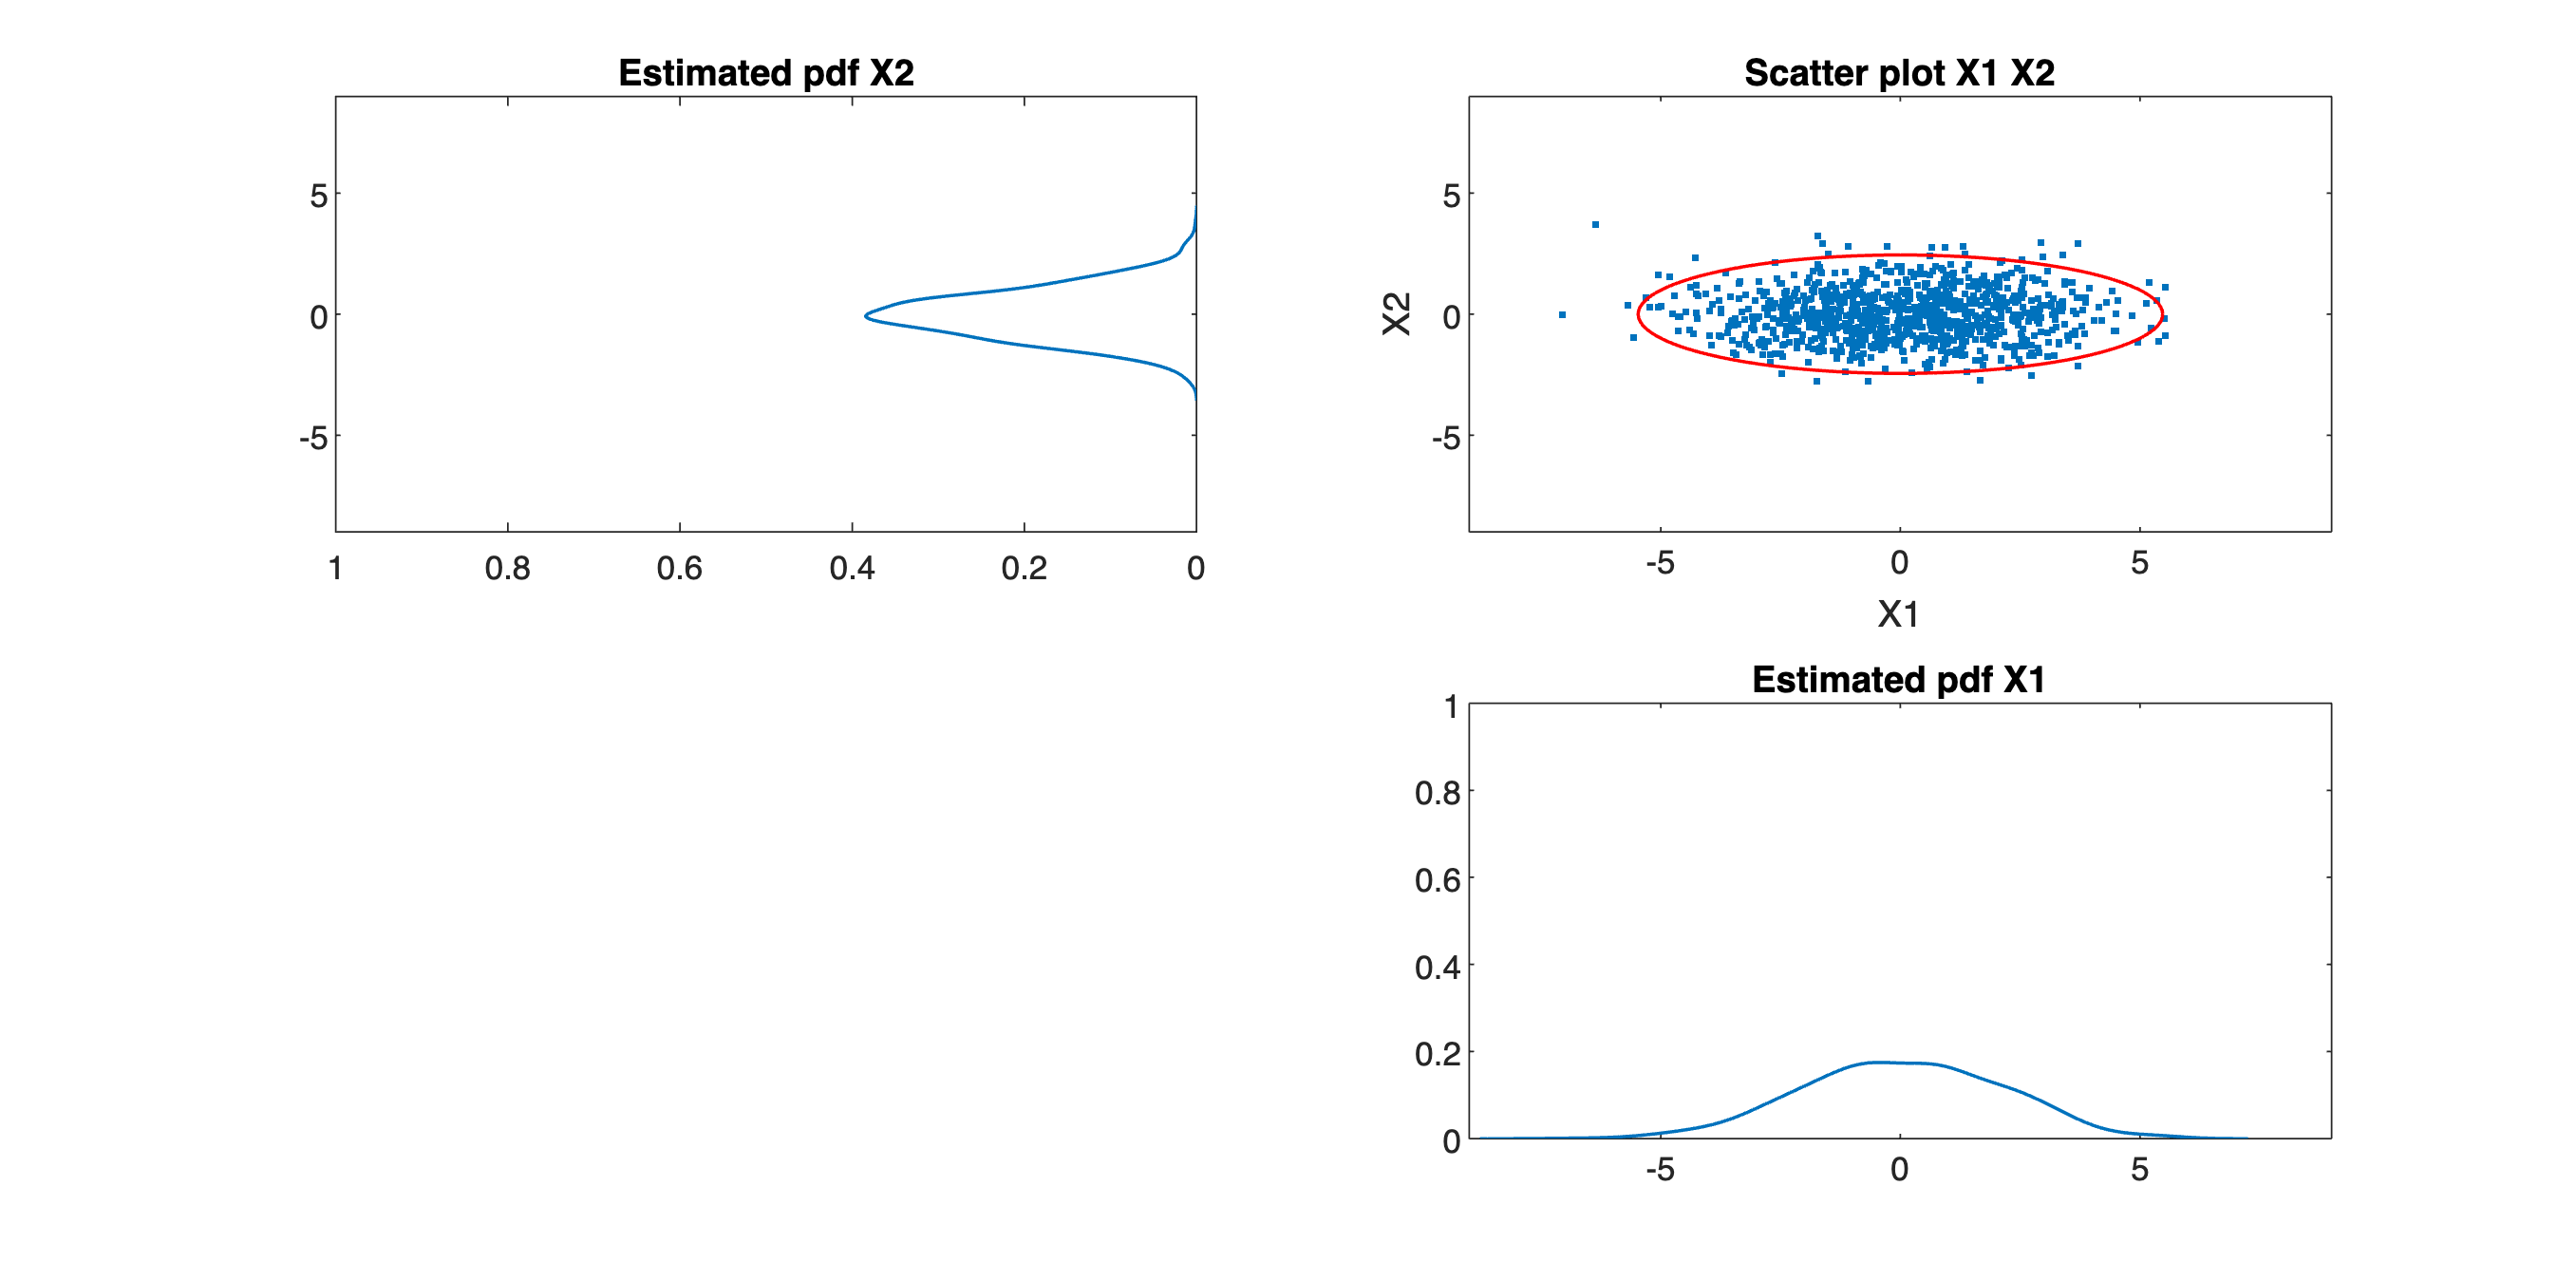



N=1000; % number of samples
% Define the covariance matrix
c11=5;   % variance of x1
c22=1;   % variance of x2
rho=0;   % correlation between x1 and x2 (-1<=rho<=+1)
 

rho=max(rho,-1+1e-6);rho=min(rho,1-1e-6);   % Avoid numerical problems
c12=rho*sqrt(c11*c22);c21=c12;    % covariance

Mcov=[c11 c12;c21 c22];    % Covariance matrix  Observe that it is symmetric c12=c21

% Generate the noise with zero mean covariance matrix Mcov
mu=[0 0];
X = mvnrnd(mu,Mcov,N); % Generate independent distributed noise samples [z1(k) z2(k)], k=1,...,N


%
% Calculate the ellipse with probability pEllipse
%
pEllipse=0.95;    % probability to be in the ellipse    
covEllipse=MyLocalCovEllipse(Mcov,pEllipse);


% plots

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])

subplot(2,2,2)
plot(X(:,1),X(:,2),'.',covEllipse(:,1),covEllipse(:,2),'r','linewidth',1)
axis([-9 9 -9 9])

title('Scatter plot X1 X2')
xlabel('X1')
ylabel('X2')

[X1pdf,X1c] = ksdensity(X(:,1)); % Matlab function to estimate the pdf
subplot(2,2,4)
plot(X1c,X1pdf,'linewidth',1)
title('Estimated pdf X1')
axis([-9 9 0 1])

[X2pdf,X2c] = ksdensity(X(:,2)); % Matlab function to estimate the pdf
subplot(2,2,1)
plot(X2pdf,X2c,'linewidth',1)
axis([0 1 -9 9])
set ( gca, 'xdir', 'reverse' )
title('Estimated pdf X2')


% Estimate the covariance and correlation matrix 
McovEst=cov(X); % estimated covariance matrix
disp('Estimated covariance matrix');

Estimated covariance matrix


disp(McovEst)

    4.2700    0.0471
    0.0471    1.0354



rhoEst=McovEst(1,2)/sqrt(McovEst(1,1)*McovEst(2,2));  % estimated correlation
McorrEst=[1 rhoEst;rhoEst 1]; % estimated correlation matrix
disp('Estimated correlation matrix');

Estimated correlation matrix


disp(McorrEst)

    1.0000    0.0224
    0.0224    1.0000


## Illustrations

In this section, we illustrate the **typical use of the covariance matrix** on two examples

- In the first one the variance of a multivariate function is calculated. It will be shown that not only the variances are important, also the covariance has a strong impact on the output variance. 

- In the second example, the slope $a$ and the offset $b$ of the linear model $y=au+b$ is estimated. The covariance matrix $C_\theta$ of the estimated parameters $\hat \theta = [\hat a ,  \hat b] $ is studied, and the variance $\sigma_y^2$ of the estimated output is calculated.

### Variance of a Multivariate Function

Consider the continuous, differentiable function $y = g(X)$ in the point $X_0$. The variance $\sigma_y^2$ due to random variations around $X_0$ with covariance matrix $C_X$ can be approximated by


$$\sigma_y^2 = JC_XJ^t$$


with $J=\frac{\partial g}{\partial X}=[\frac{\partial g}{\partial X_1} \ldots \frac{\partial g}{\partial X_n}]$. For a function with two inputs, this becomes

$\sigma_y^2= (\frac{\partial g}{\partial X_1})^2\sigma_{X_1}^2 + (\frac{\partial g}{\partial X_2})^2\sigma_{X_2}^2+2\frac{\partial g}{\partial X_1}\frac{\partial g}{\partial X_2}\sigma_{X_{12}}^2$.

To illustrate this, we consider the simple example $y=X_1 + X_2$. In that case $J=[ 1,1]$ and the variance is

$\sigma_y^2=\sigma_{X_1}^2 + \sigma_{X_2}^2+2\sigma_{X_{12}}^2=\sigma_{X_1}^2 + \sigma_{X_2}^2+2\rho_{X_{12}}\sigma_{X_1}^2\sigma_{X_2}^2$.

In this demo we generate $N$=10000 samples of a two dimensional normal distribution $X\sim N(0,C)$with zero mean and covariance matrix $C$.  The reader can set the variances $c11= \sigma_1^2, c22= \sigma_2^2$, and the correlation coefficient $rho=\rho_{12}=\frac{\sigma_{12}^2}{\sigma_1 \sigma_2}$.  A scatter plot of $X$ is shown on the left side. The middle plot shows the function $y=X_1 + X_2$. The estimated pdf of $y$ is plotted on the right side. Study the following settings:

- Put c11=5, c22=5, rho=0. The estimated variance $\hat\sigma_y^2\approx\sigma_{X_1}^2+\sigma_{X_2}^2=10$. 

- Set the value of $\rho$ to rho=0.5. Observe that the variations of $y$ grow for increasing values of rho. The variations of $y$ go to zero when rho approaches -1. 

- For rho=0, we have that $\sigma_y^2=\sigma_{X_1}^2 + \sigma_{X_2}^2$. For equal variances, $\sigma_y^2=2\sigma_X^2$. For $n$ variables this would be $\sigma_y^2=n\sigma_X^2$, or $\sigma_y=\sqrt{n}\sigma_X$.

- For rho=1, $\sigma_y^2=\sigma_{X_1}^2 + \sigma_{X_2}^2+2\sigma_{X_{1}}\sigma_{X_2}=(\sigma_{X_1}+\sigma_{X_2})^2$, and for equal variances $\sigma_y^2=4\sigma_X^2$. For $n$ variables this would be $\sigma_y^2=n^2\sigma_X^2$, or $\sigma_y=n\sigma_X$. Note that the standard deviation $\sigma_y$ grows much faster with $n$ for highly correlated variables ($\sigma_y \sim n$) than for uncorrelated variables ($\sigma_y \sim \sqrt{n}$).

- For rho=-1, $\sigma_y^2=\sigma_{X_1}^2 + \sigma_{X_2}^2-2\sigma_{X_{1}}\sigma_{X_2}=(\sigma_{X_1}-\sigma_{X_2})^2$, and for equal variances $\sigma_y^2=0$.

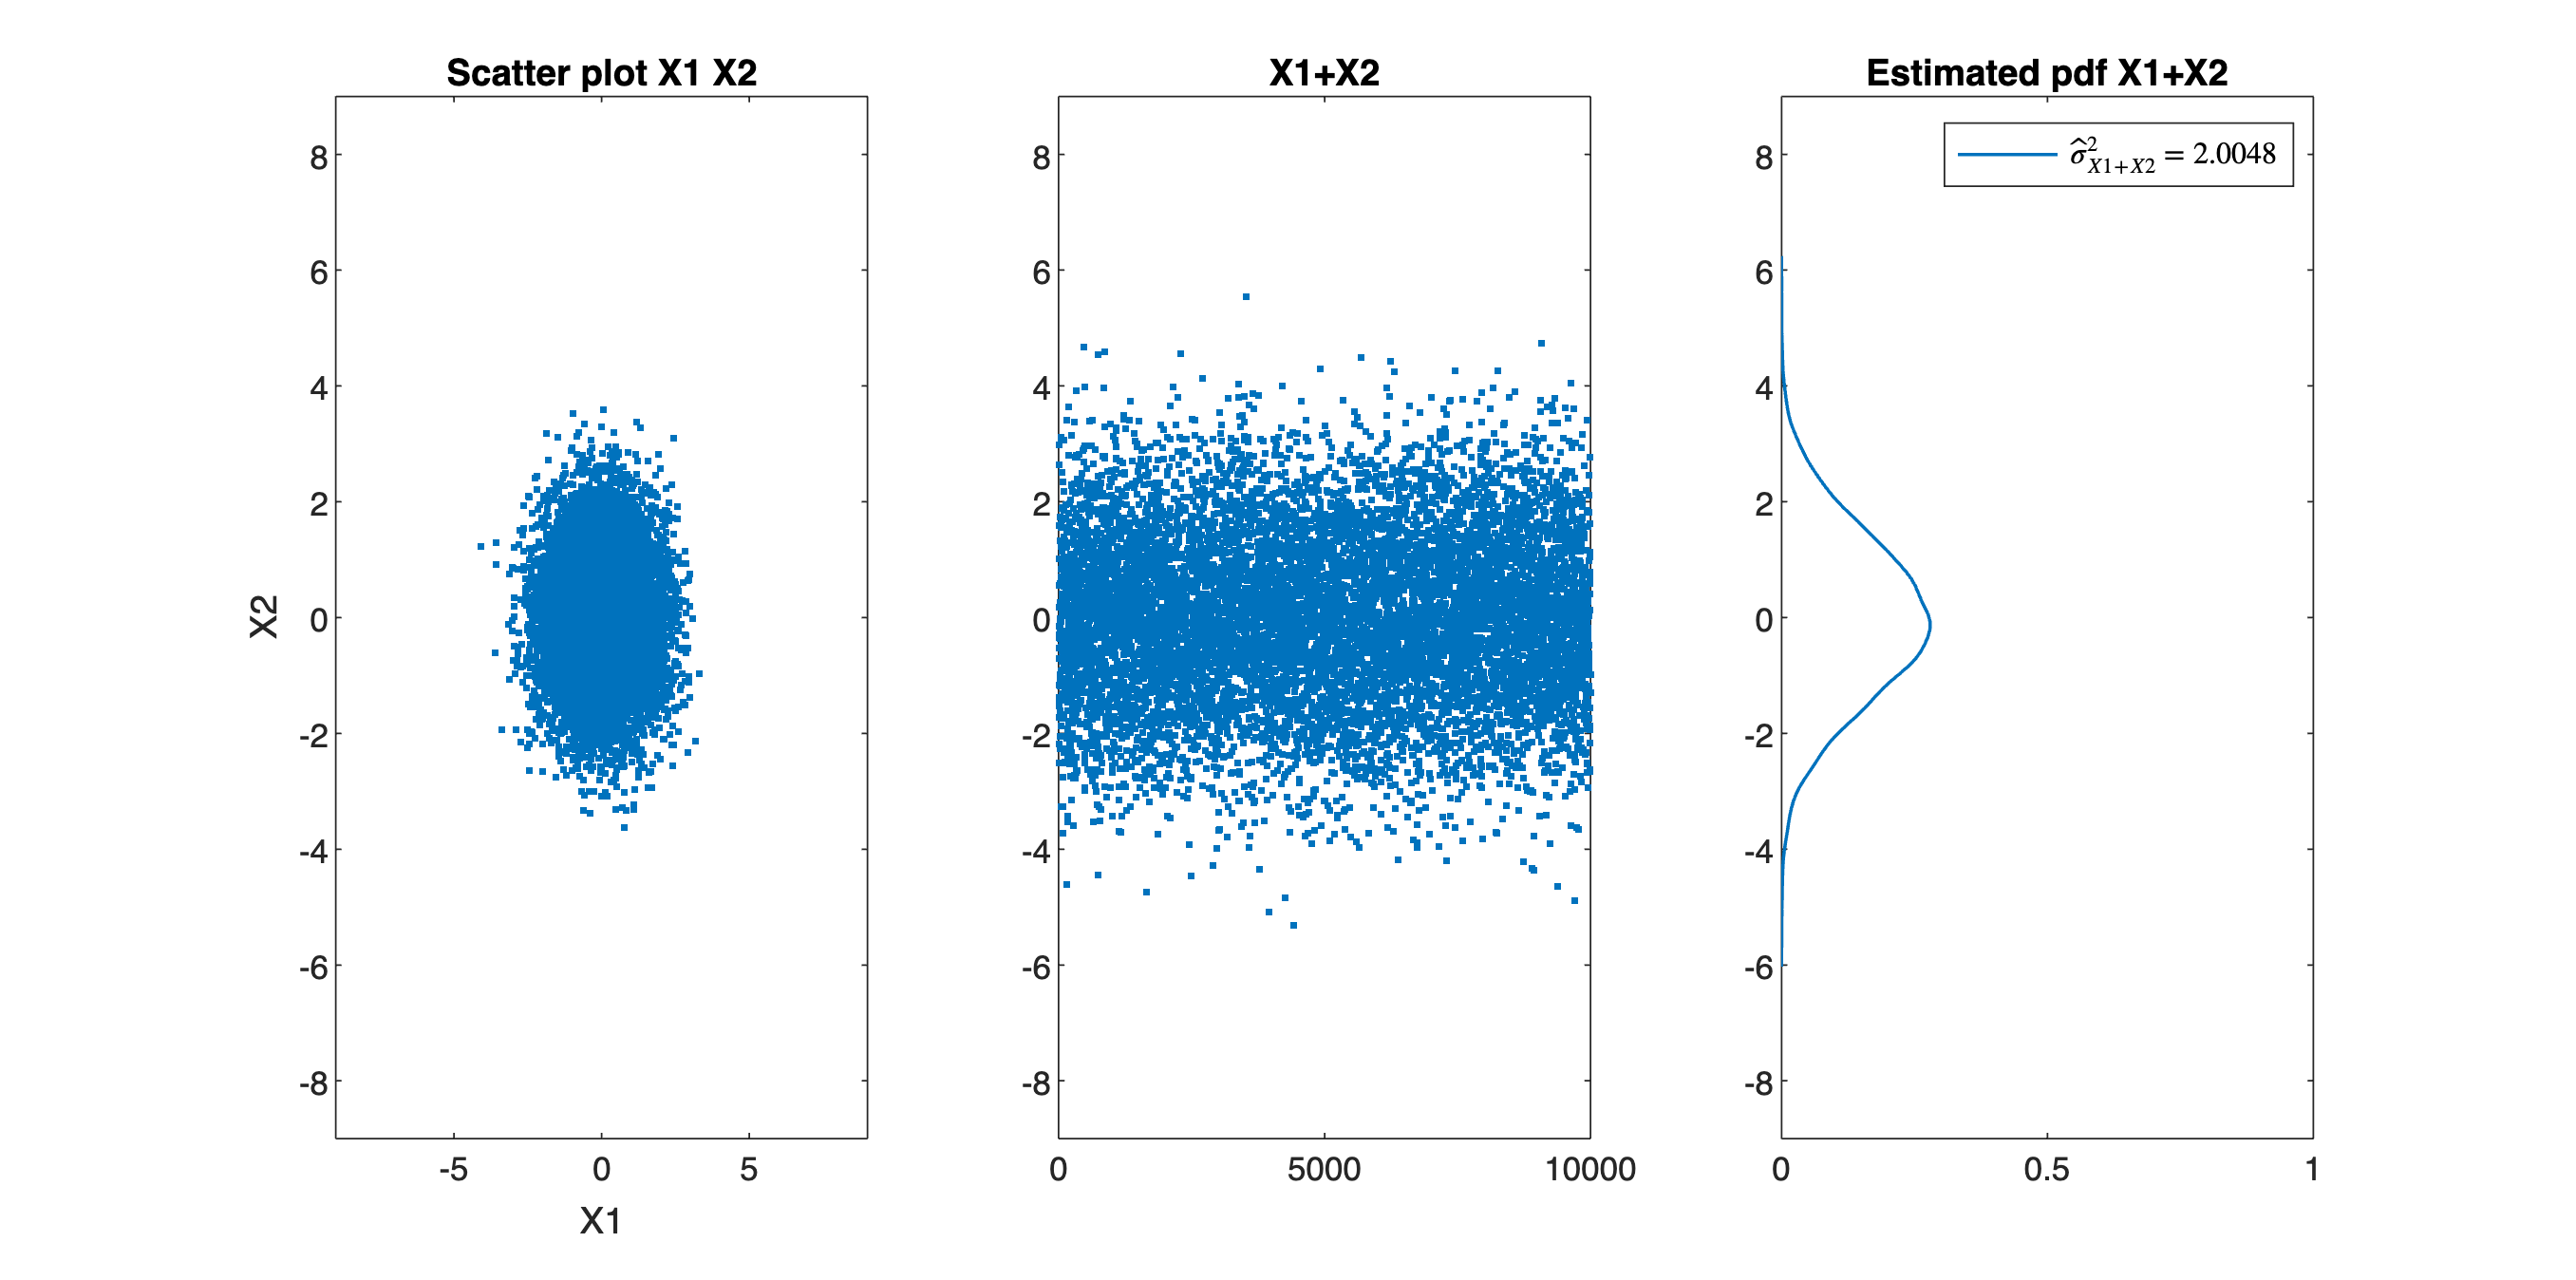

N=10000;                          % number of samples
% Define the covariance matrix
c11=1;   % variance of x1
c22=1;   % variance of x2
rho=0;   % correlation between x1 and x2 (-1<=rho<=+1)

rho=max(rho,-1+1e-6);rho=min(rho,1-1e-6);   % Avoid numerical problems
c12=rho*sqrt(c11*c22);c21=c12;    % covariance

Mcov=[c11 c12;c21 c22];    % Covariance matrix  Observe that it is symmetric c12=c21

% Generate the noise with zero mean covariance matrix Mcov
mu=[0 0];
X = mvnrnd(mu,Mcov,N); % Generate independent distributed noise samples [z1(k) z2(k)], k=1,...,N

% Study of X(:,1)+X(:,2)
Xsum=X(:,1)+X(:,2);

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])
subplot(1,3,1)
plot(X(:,1),X(:,2),'.')
axis([-9 9 -9 9])

title('Scatter plot X1 X2')
xlabel('X1')
ylabel('X2')
title('Scatter plot X1 X2')

subplot(1,3,2)
plot(Xsum,'.')
title('X1+X2')
axis([0 N -9 9])


[X2pdf,X2c] = ksdensity(Xsum); % Matlab function to estimate the pdf
subplot(1,3,3)
plot(X2pdf,X2c,'linewidth',1)
axis([0 1 -9 9])
title('Estimated pdf X1+X2')
legend(['$\hat \sigma^2_{X1+X2} = $',num2str(var(Xsum))],'interpreter','latex')

#### Exercise

Calculate the variance $\sigma_y^2$ of $y = g(X)=X_1-X_2$ due to random variations of $X_1, X_2$. For what value of $\rho$ will the variance be maximal and minimal. Compare the results with those of $y =X_1+X_2$.

### Linear Regression

Linear regression is a very popular tool in the analysis of experimental data. The true model is $y_0(k)=au(k)+b$, $k=1,\ldots,N$. The observed output $y(k) $is disturbed by zero mean uncorrelated noise with variance $\sigma_v^2$: $y(k)=y_0(k)+v(k)$. All data are stored in vectors $U,Y,V \in R^{N\times1}$, for example $U=[u(1),\ldots,u(N)]'$. The independent variable (the input) $U$ is exactly known. The parameters $\theta = [a,b]$are estimated in least square sense by minimizing the cost function $V_{LS}(\theta)=1/N \sum_{k=1}^N(y(k)-au(k)-b)^2$ with respect to $\theta$. 

The analytical solution (please refer also to the L8 part of the class materiial) of this problem is given by

 $\hat\theta=(K^tK)^{-1}K^tY$, 

with $K=[U,  1_N] \in R^{N\times2}$. The covariance matrix is

$C_{\theta}=\sigma_v^2(K^tK)^{-1}=\sigma_v^2\left[\matrix{\sum_{k=1}^{N}u(k)^2 & \sum_{k=1}^{N}u(k) \cr \sum_{k=1}^Nu(k) &N} \right]^{-1}$.

Here we illustrate the use of the covariance matrix $C_\theta$ to characterize the variability of $\hat\theta$, and the estimated output $\hat y$.

Two data sets of $N=100$ samples are created, called the blue (first) and red (second) experiment. The centers (c1, c2) and the widths (w1,w2)  of the input interval can be set for both experiments, the input is uniformly spread over the interval.  For each experiment, the estimated model (subplot 1 an 2), the uncertainty on the output (subplot 3), the estimated parameters, and the covariance ellipse  (subplot 4) are plotted. The green line is the true model. 

The simulation can be run again without changing the settings by pressing the RUN AGAIN button. This shows the impact of a new disturbing noise realization on the results. 

Study the following settings:

- Set the centers of the excitation intervals equal to c1=c2=0, and the widths w1=w2=2. Set c11 (variance of the disturbing noise) equal to 1. Observations: 1) The estimates vary from one realization to the other, every time a new simulation is run. This is because in each experiment a new realization of the disturbing noise $V$ is generated. 2) The main axis of the uncertainty ellipse are horizontal and vertical. This indicates that the correlation between the estimated slope (a) and offset (b) is zero which is so in this case because the inputs were symmetric around zero and $\sum_{k=1}^{N}u(k)=0$, so that the off-diagonal terms in $C_{\theta}$ are zero. 

- Change the widths to w1=2 (blue), w2=4 (red), and keep c1=c2=0. Observations:  1) The blue ellipse is smaller than the red one. 2) The main axes remain horizontal and vertical (no correlation). 3) The red output uncertainty is smaller than the blue one. Larger excitations result in smaller uncertainties.

- Set the centers to c1=0, c2=4, and set the widths w1=w2=2.  Observations: 1) The red ellipse is now rotated, indicating a strong correlation between $\hat a$ and $\hat b$. 2) The uncertainty on the offset $\hat b$ became much larger. 3) The standard deviation on the estimated output for both experiments is about the same in the excited intervals, although the uncertainty ellipses are very different. This is due to the impact of the covariance between the slope and offset estimate as explained in the previous section.

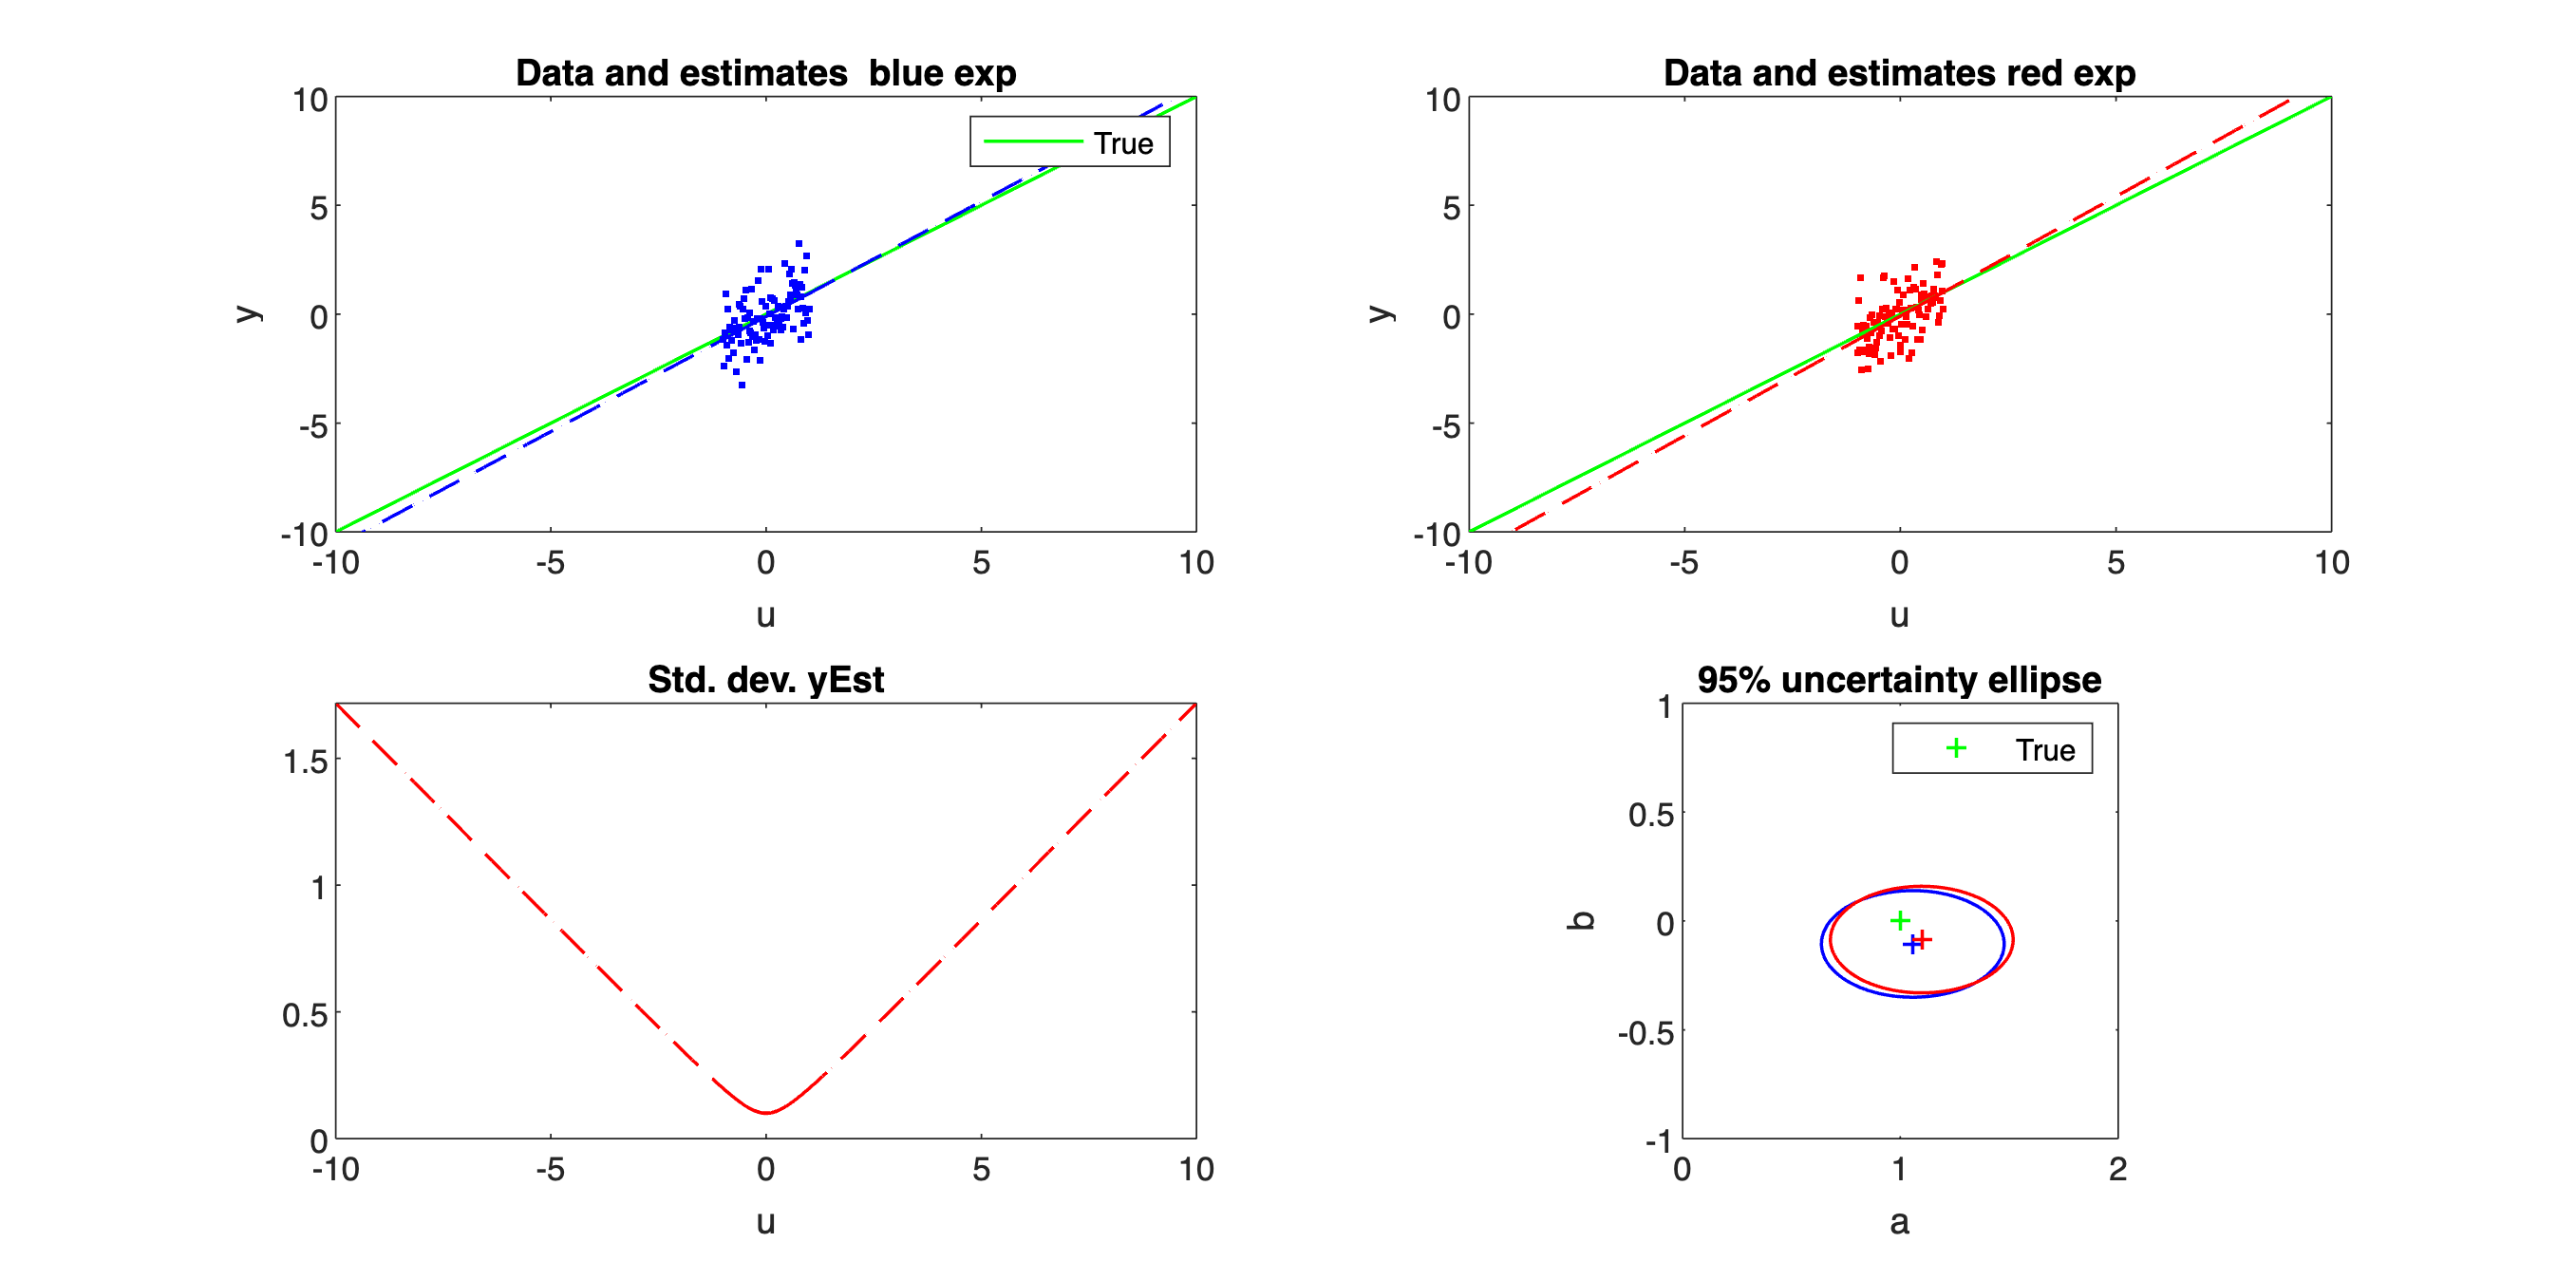


N=100;                             % number of samples
vStd=1;   % standard deviation of the disturbing noise v
c1=0;c2=0;     % minimum value of u
w1= 2;w2= 2;  % maximum value of u
 
u1Min=c1-w1/2;u1Max=c1+w1/2;    % the excited interval
u2Min=c2-w2/2;u2Max=c2+w2/2;    % the excited interval
% generate the data 
a=1;b=0; % true model y0=au+b
u0=linspace(-10,10,N)';y0=a*u0+b;    % reference model for plots
K0=[u0 ones(N,1)];

u1=linspace(u1Min,u1Max,N)';  % input blue experiment    
y1=a*u1+b+vStd*randn(size(u1));  %  y=au+b+v

u2=linspace(u2Min,u2Max,N)';  % input red experiment
y2=a*u2+b+vStd*randn(size(u2));  %  y=au+b+v

% estimates red and blue experiment
K1=[u1 ones(N,1)];
theta1=K1\y1;aEst1=theta1(1);bEst1=theta1(2);   % numerical stable solution   
yEst1=K1*theta1;                      % estimated outputs
yAllEst1=aEst1*u0+bEst1;                % plot estimated line over full interval

K2=[u2 ones(N,1)];
theta2=K2\y2;aEst2=theta2(1);bEst2=theta2(2);   % numerical stable solution   
yEst2=K2*theta2;                      % estimated outputs
yAllEst2=aEst2*u0+bEst2;                % plot estimated line over full interval

% Noise analysis red and blue experiment
C1=inv(K1'*K1)*vStd^2;                       % the covariance matrix Ctheta
for k=N:-1:1;yStd1(k)=sqrt(K1(k,:)*C1*K1(k,:)');end   % std. dev. estimated output
for k=N:-1:1;yStd1All(k)=sqrt(K0(k,:)*C1*K0(k,:)');end   % std. dev. for plot

C2=inv(K2'*K2)*vStd^2;                       % the covariance matrix Ctheta
for k=N:-1:1;yStd2(k)=sqrt(K2(k,:)*C2*K2(k,:)');end   % std. dev. estimated output
for k=N:-1:1;yStd2All(k)=sqrt(K0(k,:)*C2*K0(k,:)');end   % std. dev. for plot


figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])
subplot(2,2,1)
plot(u0,y0,'g',u1,y1,'b.',u0,yAllEst1,'--b',u1,yEst1,'b','linewidth',1)
axis([-10 10 -10 10])
xlabel('u')
ylabel('y')
title('Data and estimates  blue exp')
legend('True')

subplot(2,2,2)
plot(u2,y2,'r.',u0,y0,'g',u0,yAllEst2,'--r',u2,yEst2,'r','linewidth',1)
axis([-10 10 -10 10])
xlabel('u')
ylabel('y')
title('Data and estimates red exp')

subplot(2,2,3)
plot(u0,yStd1All,'--b',u1,yStd1,'b',u0,yStd2All,'--r',u2,yStd2,'r','linewidth',1)
axis([-10 10 0 max([yStd1All yStd2All])])
xlabel('u')
title('Std. dev. yEst')

pEllipse=0.95;
covEllipse1=MyLocalCovEllipse(C1,pEllipse);    % Uncertainty Ellipse with probability pEllipse
covEllipse2=MyLocalCovEllipse(C2,pEllipse);    % Uncertainty Ellipse with probability pEllipse 
subplot(2,2,4)
plot(a,b,'+g',aEst1,bEst1,'+b',covEllipse1(:,1)+aEst1,covEllipse1(:,2)+bEst1,'b',...
     aEst2,bEst2,'+r',covEllipse2(:,1)+aEst2,covEllipse2(:,2)+bEst2,'r',...,
    'linewidth',1)
axis([0 2 -1 1])
pbaspect([1 1 1])
xlabel('a')
ylabel('b')
legend('True')
title('95% uncertainty ellipse')



disp('Estimated blue covariance matrix');

Estimated blue covariance matrix


disp(C1)

    0.0294   -0.0000
   -0.0000    0.0100



disp('Estimated red covariance matrix');

Estimated red covariance matrix


disp(C2)

    0.0294   -0.0000
   -0.0000    0.0100


#### Exercise

From the general expression of the covariance matrix

$C_{\theta}=\left[\matrix{\sigma_a^2 &\sigma_{ab}^2 \cr \sigma_{ab}^2 &\sigma_{b}^2} \right]=\left[\matrix{\sum_{k=1}^{N}u(k)^2 & \sum_{k=1}^{N}u(k) \cr \sum_{k=1}^Nu(k) &N} \right]^{-1}=\frac{1}{N\sum_{k=1}^{N}u(k)^2-(\sum_{k=1}^Nu(k))^2}\left[\matrix{N & -\sum_{k=1}^{N}u(k) \cr -\sum_{k=1}^Nu(k) &\sum_{k=1}^{N}u(k)^2} \right]$,

we can read directly the variance of the slope $\sigma_a^2$ and the offset $\sigma_b^2$. This knowledge can be used to select the center $c$ and the width $w$ of the input interval.

- Design an experiment (choice $c, w$) that minimizes the variance $\sigma_a^2$.

- Design an experiment (choice $c, w$) that minimizes the variance $\sigma_b^2$.

- Put the values in the simulator to check the results.

## Uncorrelated and independent variables

In this section we illustrate the difference between uncorrelated and independent random variables.

Two random variables X and Y are uncorrelated if the covariance $\sigma_{XY}^2=0$.

Two random variables X and Y are independent if their distribution $F_{XY}(x,y)=F_X(x)F_Y(y), \forall x,y$. For continuous distributions this is also valid for the probability density functions:  $f_{XY}(x,y)=f_X(x)f_Y(y), \forall x,y$.

Independency is a much stronger property than being uncorrelated. Loosely spoken, independency of $X$ and $Y$ implies that the knowledge of $X$ gives no information on $Y$. However, there are some exceptions where uncorrelation implies also independency. For example, two jointly normally distributed random variables are also independent if they are uncorrelated.

In the next demo, we generate 2 data sets. The first blue data set consists of $N$ samples $(x,y)$ drawn from a two dimensional jointly normal distribution with zero mean, and covariance matrix $C=\left[\matrix{1 & 0 \cr 0 &1} \right]$. The second red data set consists of samples $(x,y=|x|)$ with $X\sim N(0,1)$. The scatter plot of both sets is plotted, and the estimated correlation coefficient for both experiments is given below the figure.

Study the following settings:

- Set the number of samples $N=100$

- Observe that the red data are clearly dependent. Knowledge of $x$ gives information about $y$.

- Run the simulation a few times. Observe that $\hat \rho$ for both data sets is close but not equal to zero, $\hat \rho$  varies from one realization to the other.

- Increase the number of samples to 10000. The estimated values of the correlation are now much closer to zero. For $N \rightarrow \infty$, the estimated correlation $\hat\rho \rightarrow 0$.

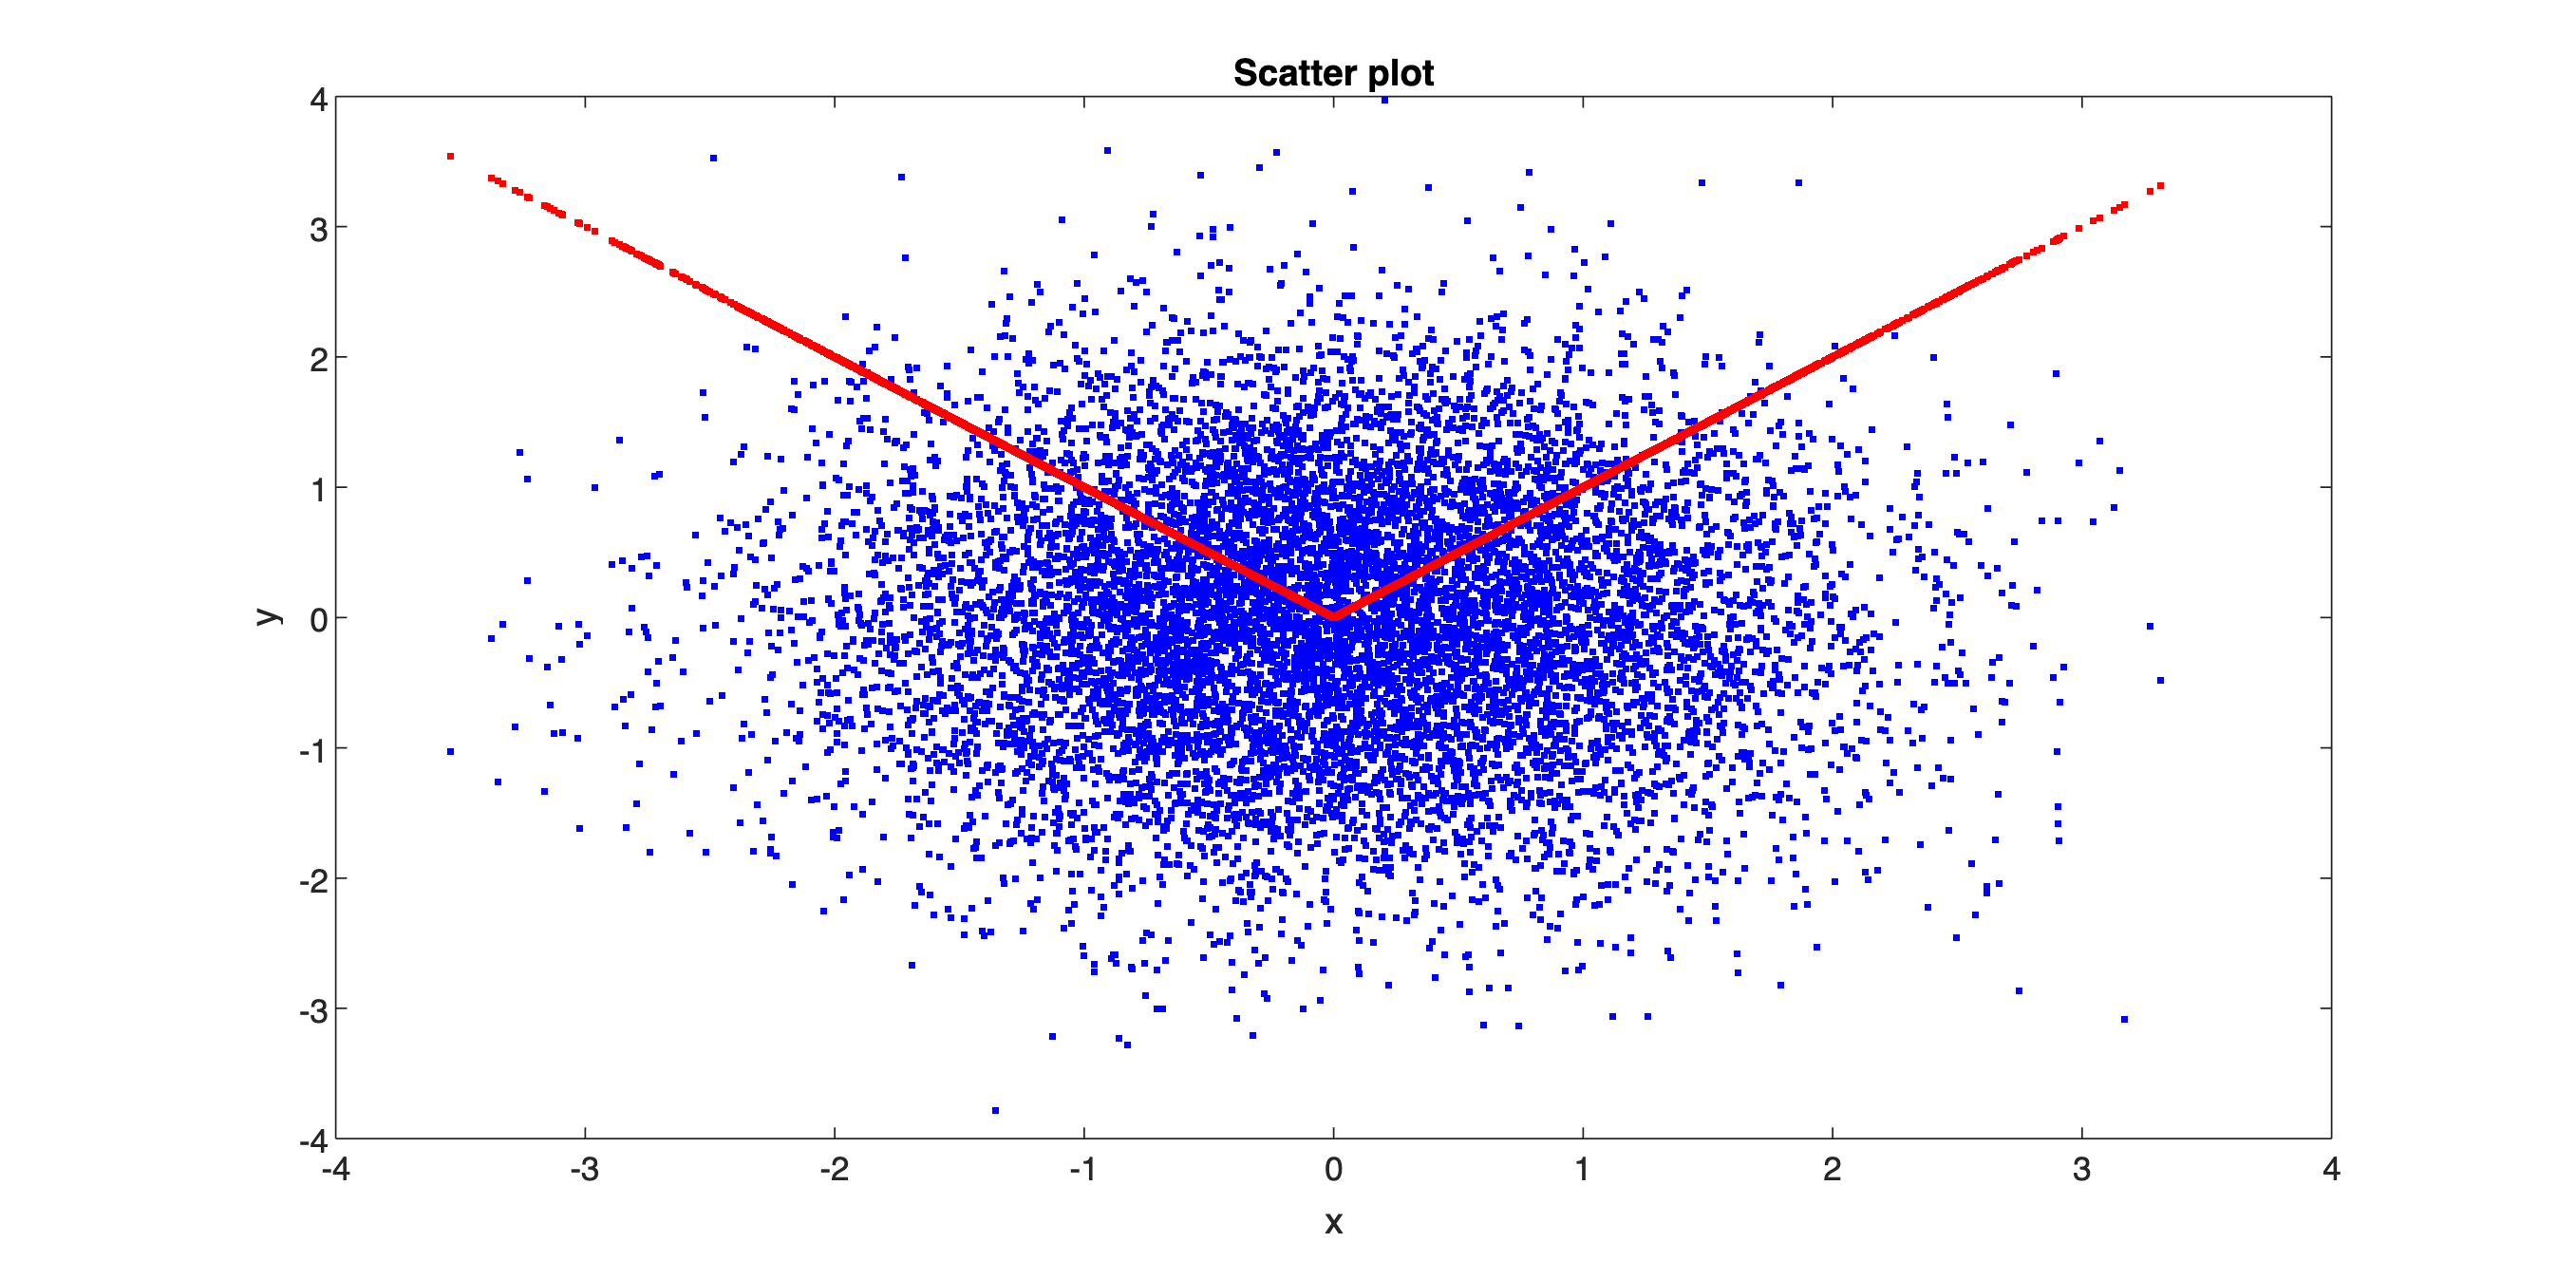


N=10000; % number of samples
 
% Generate uncorrelated noise with zero mean covariance matrix Mcov
mu=[0 0];  % zero mean
Mcov=[1 0;0 1];  % covariance matrix with unite variant
X = mvnrnd(mu,Mcov,N); % Generate independent distributed noise samples [z1(k) z2(k)], k=1,...,N

Y=abs(X(:,1));

McovEstX=cov(X);  %  estimate the covariance matrix noise
rhoX=McovEstX(1,2)/sqrt(McovEstX(1,1)*McovEstX(2,2));

McovEstY=cov([X(:,1) Y]);  %  estimate the covariance matrix quadratic function
rhoY=McovEstY(1,2)/sqrt(McovEstY(1,1)*McovEstY(2,2));

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])
%subplot(1,2,1)
plot(X(:,1),X(:,2),'.b',X(:,1),Y,'.r')
axis([-4 4 -4 4])
xlabel('x')
ylabel('y')
title('Scatter plot')

disp('Estimated correlation coefficients blue and red data');

Estimated correlation coefficients blue and red data


fprintf('rho (blue) = %4.4f\n',rhoX)

rho (blue) = -0.0042


fprintf('rho (red)  = %4.4f',rhoY)

rho (red)  = -0.0243

## What you learned

- The covariance matrix describes the joint variability of random variables around their mean value, and it will play a central role in the evaluation of the quality of estimates and their use in applications. 

- The variances characterize the variability of the individual parameters, while the covariances indicate a linear dependency between different parameter estimates. 

- If the goal of the experiment is to estimate a physical parameter, the variance on that parameter should be small.

- However, if the goal is to model the output of a multivariate function, the combined effect of the parameter uncertainties on the output of the function should be small. This might lead to a different experiment design. As a rule of thumb, the excitation should be focused on the region where $\sigma_y$ should be small. But a complely different experiment is needed if the slope or offset is the value of interest.

- For two dimensional parameters, the covariance matrix characterizes the uncertainty ellipse that can be used to generate an uncertainty region for the estimated parameters. The main axis will be horizontal and vertical if $\rho=0$, the estimates are not correlated. 

- From the linear regression example, we learned that the experiment design has a strong impact on the uncertainty ellipse and the related uncertainty on the output. 

- The correlation coefficient $\rho$ describes the strength of linear relation between the components of a multivariate distribution. 

- Uncorrelatedness does not imply independency, a counter example was given. However, for jointly normal distributed variables, both properties are equivalent.

- Finally, it was illustrated that **the result of a random experiment varies from one realization to the other, even if the settings of the simulation do not change**. 

- Under mild conditions, the variation (uncertainty) drops to zero as an $O(1/\sqrt{N})$ which is rather slow. Increasing the length of an experiment is an easy, but rather expensive way to improve the quality of the estimates. 

- The length of the experiment should be multiplied with a factor 100 to get a reduction of the uncertainty with a factor 10. A better solution is to make a proper design of the experiment.

## Solutions

### Exercise Variance of a Multivariate Function

The variance of $y=X_1-X_2$ is $\sigma_y^2=\sigma_{X_1}^2 + \sigma_{X_2}^2-2\sigma_{X_{12}}^2=\sigma_{X_1}^2 + \sigma_{X_2}^2-2\rho\sigma_{X_1}\sigma_{X_2}$. It is minimal for $\rho=1$, and maximal for $\rho = -1$. This solution can be verified in the following simulation.

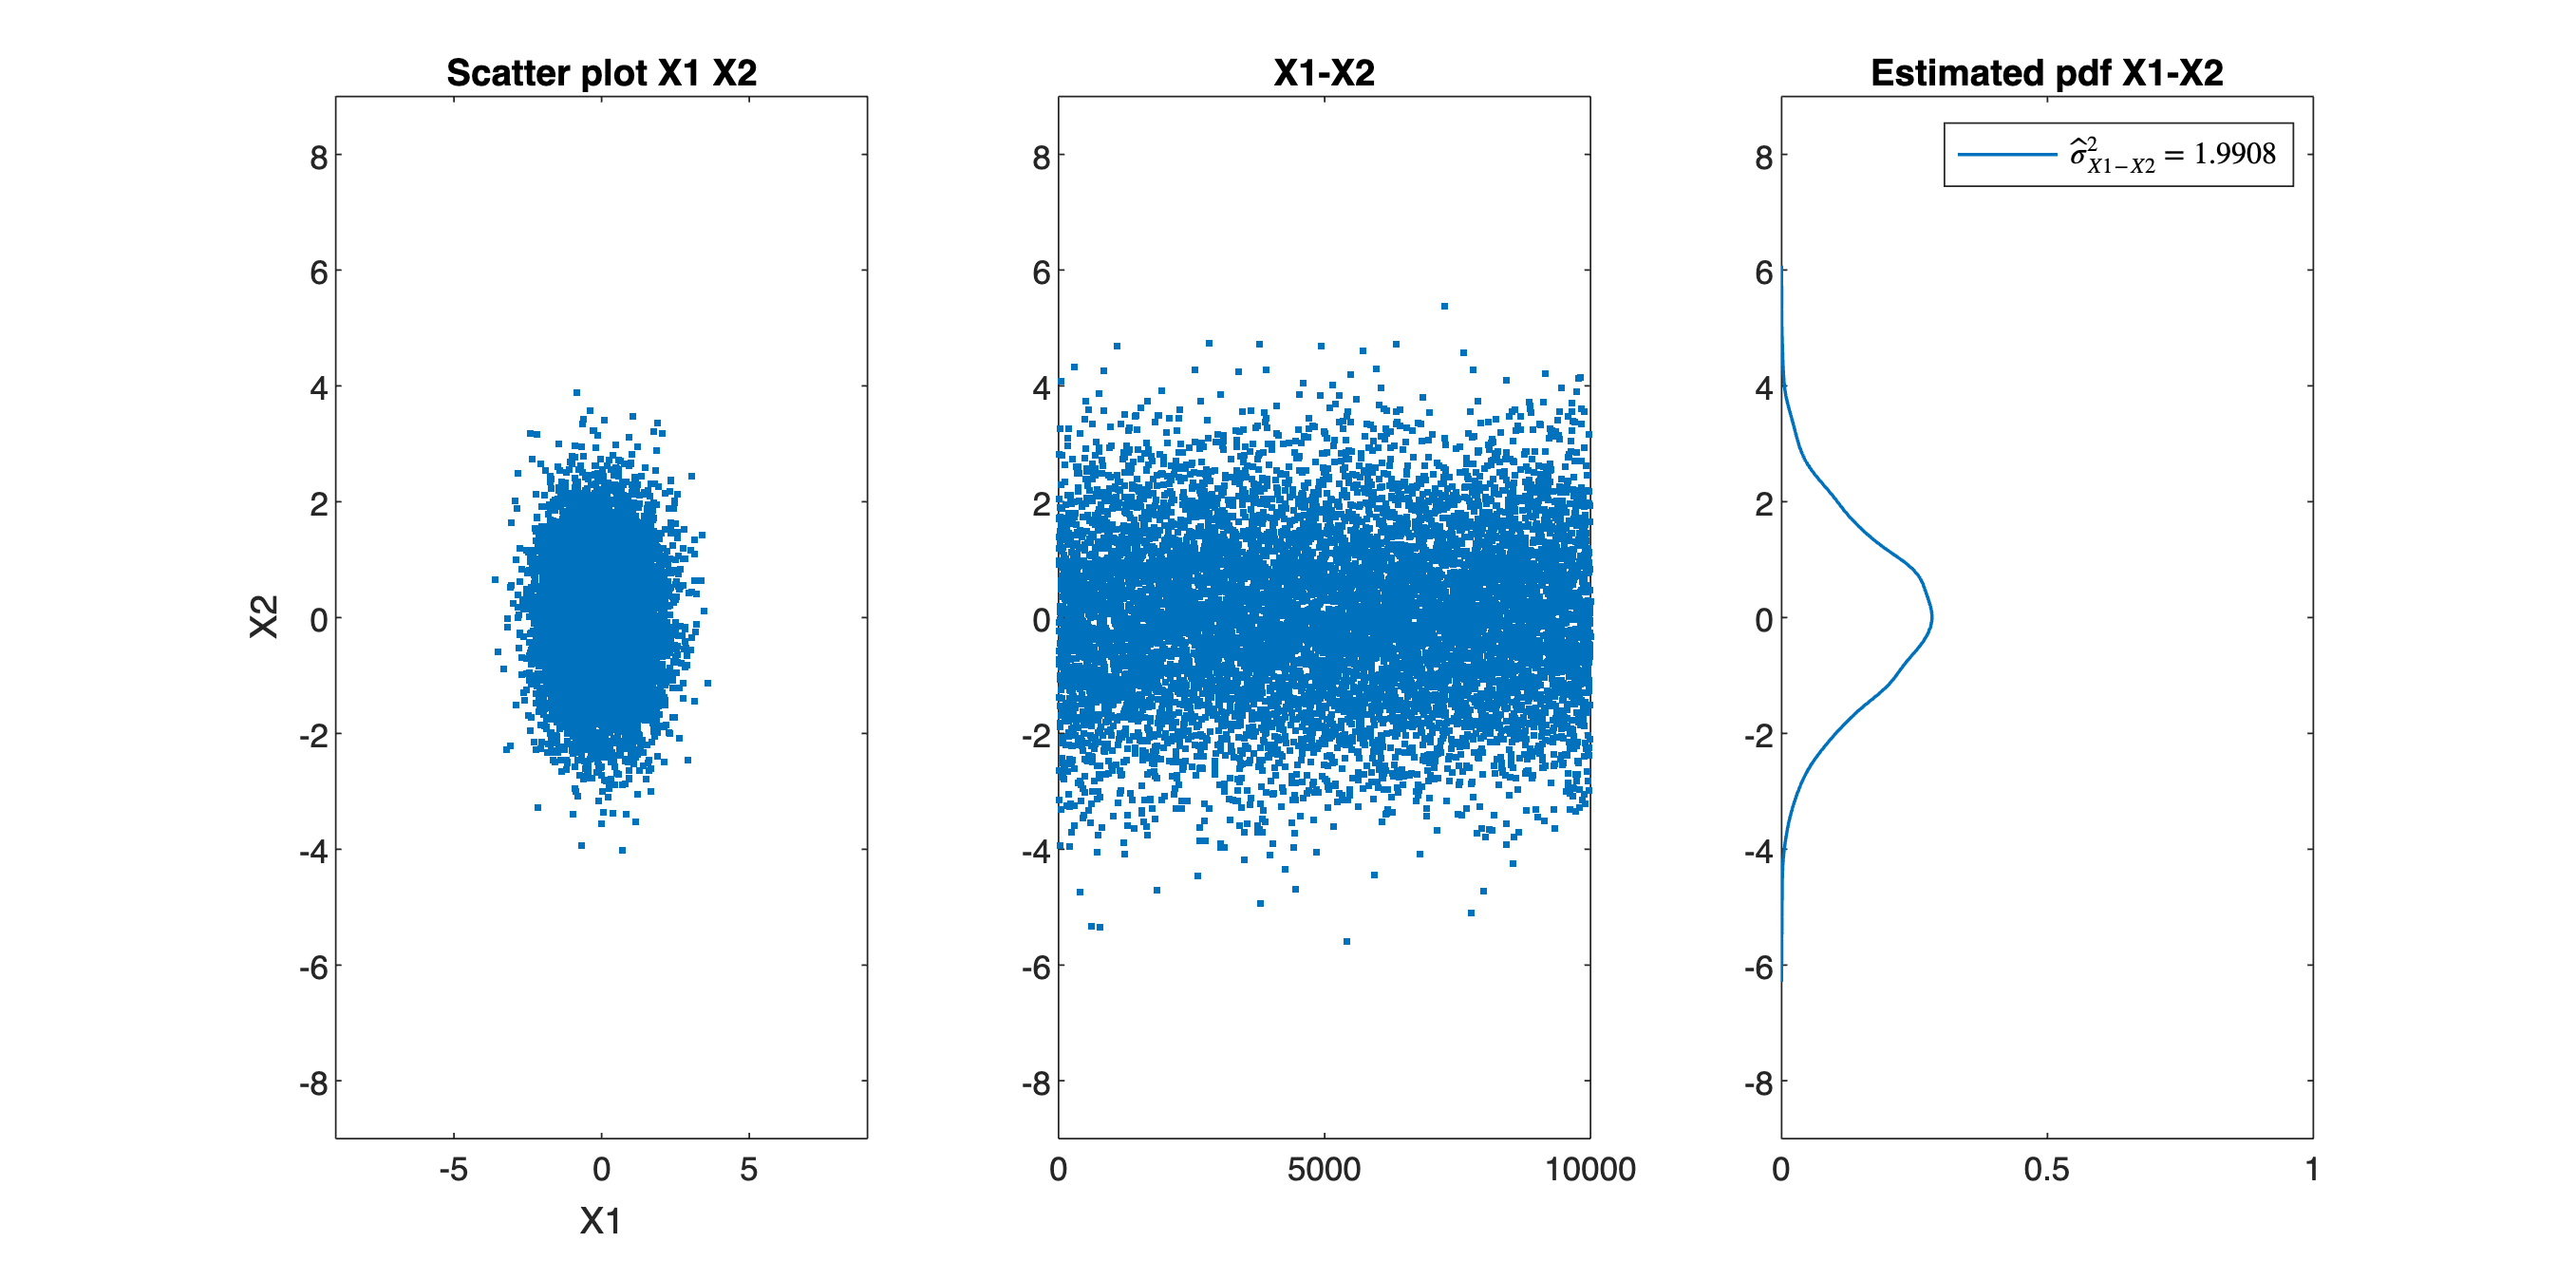


N=10000;                          % number of samples
% Define the covariance matrix
c11=1;   % variance of x1
c22=1;   % variance of x2
rho=0;   % correlation between x1 and x2 (-1<=rho<=+1)

rho=max(rho,-1+1e-6);rho=min(rho,1-1e-6);   % Avoid numerical problems
c12=rho*sqrt(c11*c22);c21=c12;    % covariance

Mcov=[c11 c12;c21 c22];    % Covariance matrix  Observe that it is symmetric c12=c21

% Generate the noise with zero mean covariance matrix Mcov
mu=[0 0];
X = mvnrnd(mu,Mcov,N); % Generate independent distributed noise samples [z1(k) z2(k)], k=1,...,N

% Study of X(:,1)-X(:,2)
Xdiff=X(:,1)-X(:,2);

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])
subplot(1,3,1)
plot(X(:,1),X(:,2),'.')
axis([-9 9 -9 9])

title('Scatter plot X1 X2')
xlabel('X1')
ylabel('X2')
title('Scatter plot X1 X2')

subplot(1,3,2)
plot(Xdiff,'.')
title('X1-X2')
axis([0 N -9 9])


[X2pdf,X2c] = ksdensity(Xdiff); % Matlab function to estimate the pdf
subplot(1,3,3)
plot(X2pdf,X2c,'linewidth',1)
axis([0 1 -9 9])
title('Estimated pdf X1-X2')
legend(['$\hat \sigma^2_{X1-X2} = $',num2str(var(Xdiff))],'interpreter','latex')

### Exercise Linear Regression

Check that the  determinant $D=N(\sum_{k=1}^{N}u(k)^2-(\sum_{k=1}^Nu(k))^2)$ does not depend on $c$, the center of the interval (for a uniformly spread input over the interval) and equals $D=N\sum_{k=1}^Nz(k)^2$, with $z(k)=u(k)-c$ . Observe the similarity with $\sigma^2=E[X^2]-(E[x])^2=E[(X-E[X])^2]$.  

- The slope variance becomes $\sigma_a^2=\frac{1}{\sum_{k=1}^{N}z(k)^2}}$. Observe that this result is independent of the center $c$ of the interval. The sum  $\sum_{k=1}^{N}z(k)^2}$ should be maximized. In the simulation, this can be done by increasing the width of the interval. 

- The offset variance becomes $\sigma_b^2=\frac{Nc^2+\sum_{k=1}^{N}z(k)^2}{N\sum_{k=1}^{N}z(k)^2}}$. It will be minimized for $c=0$ which corresponds to an input that is symmetric around zero. 

Remarks: 

- The sum $\sum_{k=1}^{N}z(k)^2 = O(N)$, which implies that the variances $\sigma_a^2, \sigma_b^2$ are an $O(N^{-1})$, hence the standard deviations $\sigma_a, \sigma_b$ drop in $1/\sqrt{N}$ to zero. Increasing the number of samples reduces the uncertainty on the estimates.

- Both variances are simultaneously minimized by putting the center of the interval $c=0$, and maximizing the width $w$ of the interval.

function covEllipse=MyLocalCovEllipse(Mcov,pEllipse,NEllipse)
%
% Calculation of the ellipse that contains a user specified probability mass
%
% Input arguments
%    Mcov:  2x2 covariance matrix
%    pEllipse: the probability level of the ellipse
%    NEllipse: number of points 
% Output 
%    covEllipse: NEllipsex2 matrix with the calculated points
%
% Copyright  Johan Schoukens 06/06/2019

% Default choices
NEllipseDefault=100;  % number of points to be calculated
pEllipseDefualt=0.5;  % the probability included in the ellipse

switch nargin   % set the default values
    case 3
        % All inputs are defined
    case 2
        NEllipse=NEllipseDefault;    % number of points to be calculated
    case 1
        pEllipse=pEllipseDefualt;    % the probability included in the ellipse
        NEllipse=NEllipseDefault;    % number of points to be calculated
    otherwise
        disp('The covariance matrix should be specified')
end

scaleEllipse=sqrt(chi2inv(pEllipse,2));     % scale factor for the ellipse

T= chol(Mcov);  % decompose the covariance matrix C = T'*T using the Cholesky factorization

theta=2*pi*[0:NEllipse]/NEllipse;
covCircle(:,1)=cos(theta);covCircle(:,2)=sin(theta);
covEllipse=scaleEllipse*covCircle*T;

end